# Make pictures for the Fourier Transform

Make images of harmonics (fx,fy), which the MRI community describes as k-space (kx,ky).  Show them as images and as amplitudes of the FFT.

BW, Vistasoft Team, 2018

## A harmonic in the X dimension

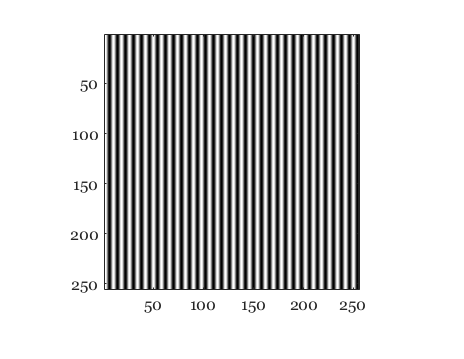

nSamp = 256;
x = linspace(1/nSamp,1,nSamp); y = x;
fx = 24;
fy = 0;
[X,Y] = meshgrid(x,y);
im = sin(2*pi*(fx*X + fy*Y));
mrvNewGraphWin;
imagesc(im); colormap(gray); truesize;

## Amplitude of the Fourier Transform coefficients

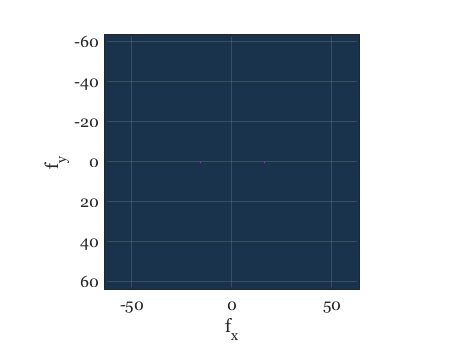

imFT = abs(fft2(im));
imFT = fftshift(imFT);

mrvNewGraphWin;
mp = colormap(cool);
mp(1:20,:) = repmat([0.1,0.2,0.3],20,1);
imagesc((x - 0.5)*(nSamp/2), (y - 0.5)*(nSamp/2), imFT.^0.3); colormap(mp);
grid on; truesize
set(gca,'GridColor',[0.9 0.9 0.9]);
xlabel('f_x'); ylabel('f_y');

% mesh(imFT)

## A harmonic in the Y dimension

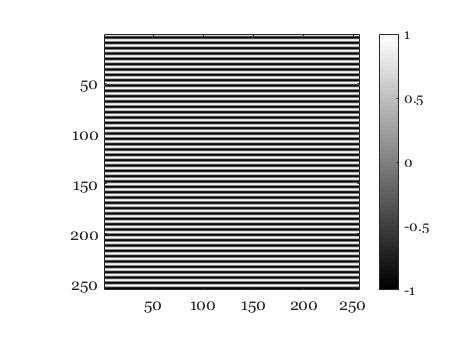

fy = 32;
fx  = 0;
im = sin(2*pi*(fx*X + fy*Y));
mrvNewGraphWin;
imagesc(im); colormap(gray); colorbar; truesize;

## Fourier Transform amplitudes

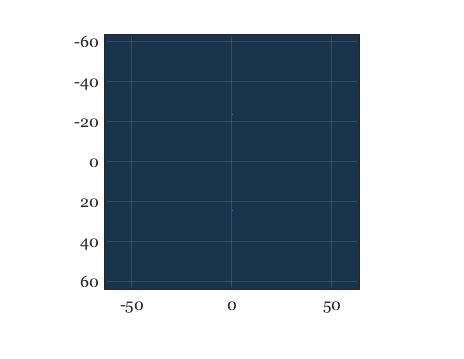

imFT = abs(fft2(im));
imFT = fftshift(imFT);

mrvNewGraphWin;
imagesc((x - 0.5)*(nSamp/2), (y - 0.5)*(nSamp/2), imFT.^0.3); colormap(mp);
grid on;  truesize
set(gca,'GridColor',[0.9 0.9 0.9])

## Sum of the two harmonics

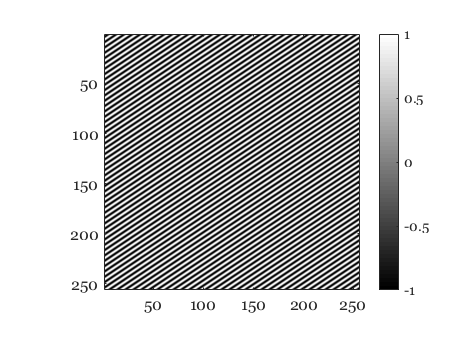

fy = 32;
fx = 24;
mrvNewGraphWin;
im = sin(2*pi*(fx*X + fy*Y));
imagesc(im); colormap(gray); colorbar; truesize;

## Fourier Transform of the sum

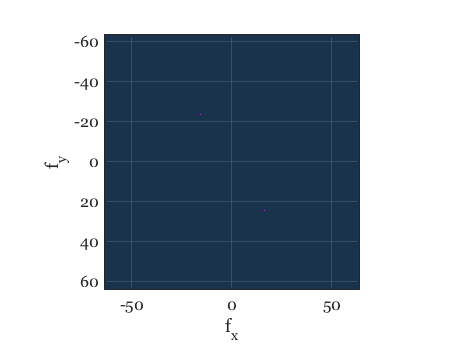


imFT = abs(fft2(im));
imFT = fftshift(imFT);

mrvNewGraphWin;
imagesc((x - 0.5)*(nSamp/2), (y - 0.5)*(nSamp/2), imFT.^0.3); colormap(mp);
grid on; truesize
set(gca,'GridColor',[0.9 0.9 0.9]);
xlabel('f_x'); ylabel('f_y');